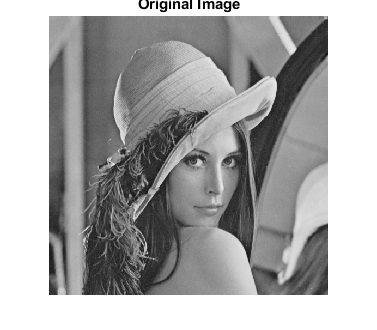

% Q1
I = im2uint8(rgb2gray(imread("lena_std.tif")));
imshow(I), title("Original Image");

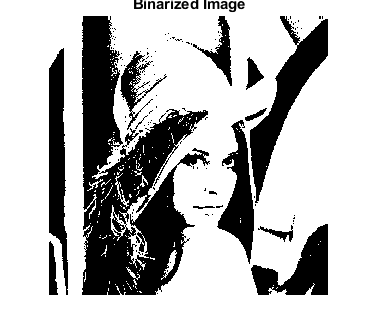

bin = imbinarize(I);
imshow(bin), title("Binarized Image");

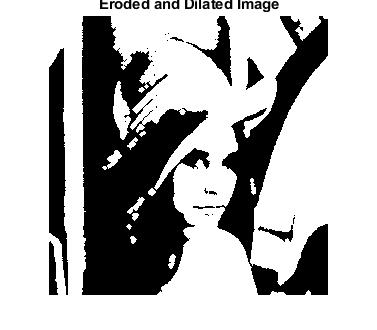

se = strel('disk',2);
q1 = imerode(imerode(bin,se),se);
q1 = imdilate(imdilate(q1,se),se);
q1_r = imdilate(imdilate(bin,se),se);
q1_r = imerode(imerode(q1_r,se),se);
imshow(q1), title("Eroded and Dilated Image");

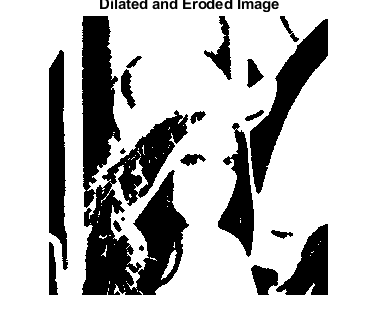

imshow(q1_r), title("Dilated and Eroded Image");

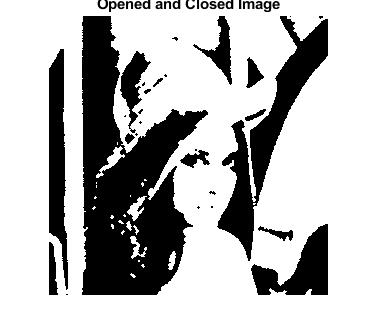


% Q2
se = strel('disk',2);
q2 = imopen(imopen(bin,se),se);
q2 = imclose(imclose(q2,se),se);
q2_r = imclose(imclose(bin,se),se);
q2_r = imopen(imopen(q2_r,se),se);
imshow(q2), title("Opened and Closed Image");

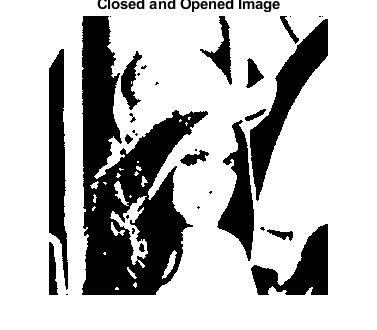

imshow(q2_r), title("Closed and Opened Image");

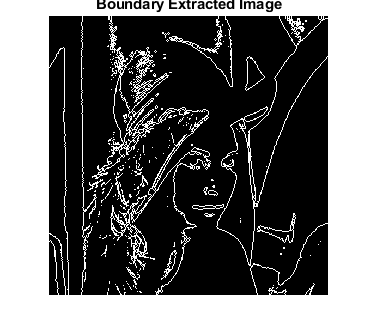


% Q3
se = strel('disk',2);
beta = imerode(bin,se);
q3 = bin-beta;
imshow(q3), title("Boundary Extracted Image");

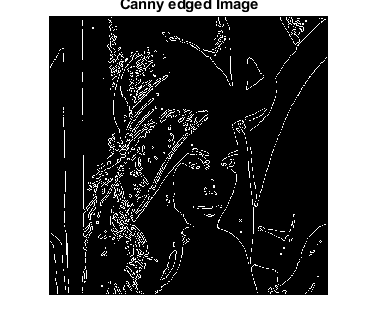

ed = edge(bin,'canny');
imshow(ed), title("Canny edged Image");